# Mehdi Muzaffari - MAE 674 - Project 1

clc;
clear;
close all;

## load simulated Data

data = readtable('simulation');
time = data.Time;
theta1_true = data.Theta1;
theta1_dot_true = data.Theta1_Dot;
theta2_true = data.Theta2;
theta2_dot_true = data.Theta2_Dot;

## add noise to data

noise_std_theta1 = 0.05;
noise_std_theta1_dot = 0.03;
noise_std_theta2 = 0.04;
noise_std_theta2_dot = 0.02;

theta1_measured = theta1_true + noise_std_theta1 * randn(size(theta1_true));
theta1_dot_measured = theta1_dot_true + noise_std_theta1_dot * randn(size(theta1_dot_true));
theta2_measured = theta2_true + noise_std_theta2 * randn(size(theta2_true));
theta2_dot_measured = theta2_dot_true + noise_std_theta2_dot * randn(size(theta2_dot_true));

## simulation parameters

dt = 0.01;
num_steps = length(time);

theta1 = pi/4;
theta1_dot = 0;
theta2 = pi/6;
theta2_dot = 0;

x_hat = [pi/4; 0; pi/6; 0];
P = diag([0.01, 0.1, 0.01, 0.01]);
Q = diag([0.01, 0.01, 0.01, 0.01]);
R = diag([0.05, 0.05, 0.05, 0.05]);

## ukf parameters

alpha = 1e-3;
kappa = 0;
beta = 2;
n = 4;
lambda = alpha.^2 * (n + kappa) - n;
gamma = sqrt(n + lambda);

Wm = [lambda / (n + lambda), repmat(0.5 / (n + lambda), 1, 2 * n)];
Wc = Wm;
Wc(1) = Wc(1) + (1 - alpha^2 + beta);

x_hat_history = zeros(n, num_steps);
P_hat_history = zeros(n, n, num_steps);

x_hat_history(:, 1) = x_hat;
P_hat_history(:, :, 1) = P;

tic;
for k = 2:num_steps

    X = [x_hat, x_hat + gamma * chol(P)', x_hat - gamma * chol(P)'];

    X_pred = zeros(size(X));

    for i = 1:size(X, 2)

        theta1 = X(1, i);
        theta1_dot = X(2, i);
        theta2 = X(3, i);
        theta2_dot = X(4, i);

        [theta1_ddot, theta2_ddot] = dynamic(theta1, theta1_dot, theta2, theta2_dot);

        X_pred(:, i) = [theta1 + dt * theta1_dot; theta1_dot + dt * theta1_ddot;
            theta2 + dt * theta2_dot; theta2_dot + dt * theta2_ddot];
    end

    x_pred = X_pred * Wm';

    P_pred = Q;
    for i = 1:size(X, 2)
        P_pred = P_pred +  Wc(i) * (X_pred(:, i) - x_pred) * (X_pred(:, i) - x_pred)';
    end

    X_update = [x_pred, x_pred + gamma * chol(P_pred)', x_pred - gamma * chol(P_pred)'];

    Z_pred = X_update;
    z_pred = Z_pred * Wm';

    S = R;
    for i = 1:size(X_update, 2)
        S = S + Wc(i) * (Z_pred(:, i) - z_pred) * (Z_pred(:, i) - z_pred)';
    end

    C = zeros(n);
    for i = 1:size(X_update, 2)
        C = C + Wc(i) * (X_pred(:, i) - x_pred) * (Z_pred(:, i) - z_pred)';
    end

    K = C / S;
    z = [theta1_measured(k); theta1_dot_measured(k); theta2_measured(k); theta2_dot_measured(k)];
    x_hat = x_pred + K * (z - z_pred);
    P = P_pred - K * S * K';

    x_hat_history(:, k) = x_hat;
    P_hat_history(:, :, k) = P;

end

elapsed_time = toc;

## plots

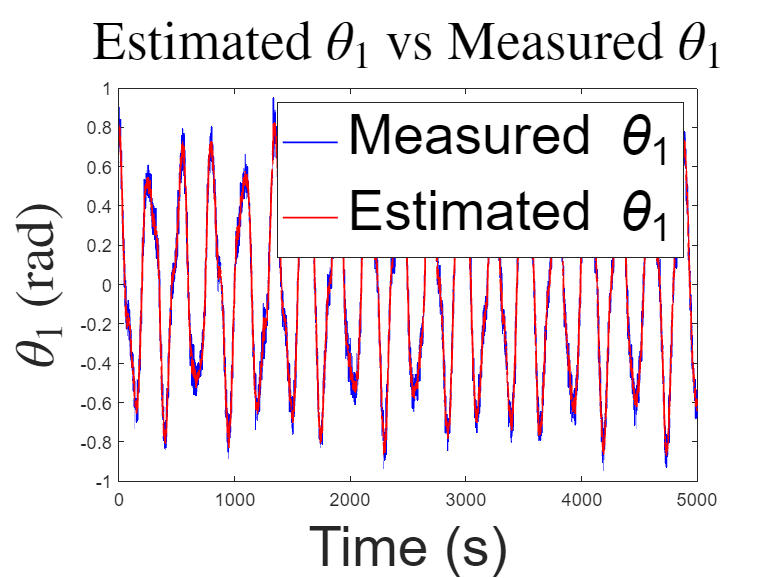

figure;
plot(time, theta1_measured, 'DisplayName', 'Measured \theta_1', 'Linewidth', 1.0, 'Color', 'b', 'LineStyle','-');
hold on
plot(time, x_hat_history(1, :), 'DisplayName', 'Estimated \theta_1', 'Linewidth', 1.0, 'Color', 'r', 'LineStyle','-');
hold off
xlabel('Time (s)', 'FontSize', 30);
ylabel('$\theta_1$ (rad)', 'Interpreter', 'latex', 'FontSize', 30);
legend ('FontSize', 30);
title('Estimated $\theta_1$ vs Measured $\theta_1$', 'Interpreter', 'Latex', 'FontSize', 30);

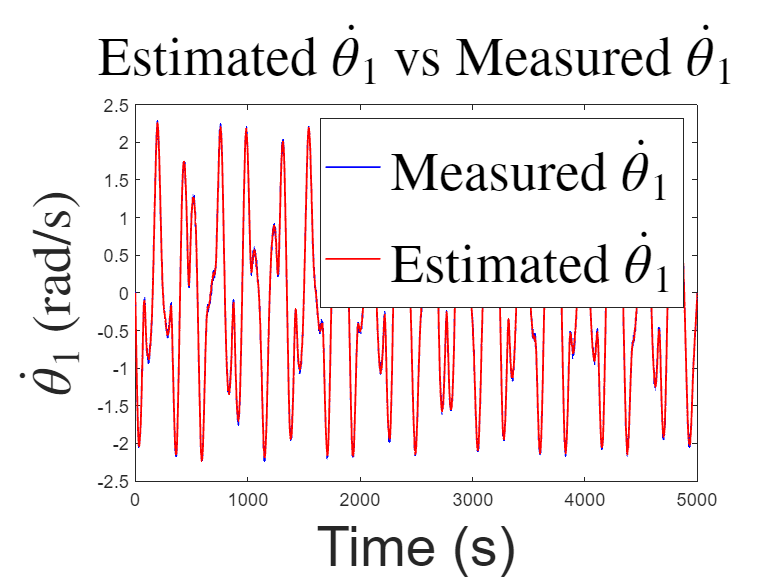

figure;
plot(time, theta1_dot_measured, 'DisplayName', 'Measured $\dot{\theta}_1$', 'Linewidth', 1.0, 'Color', 'b', 'LineStyle','-');
hold on
plot(time, x_hat_history(2, :), 'DisplayName', 'Estimated $\dot{\theta}_1$', 'Linewidth', 1.0, 'Color', 'r', 'LineStyle','-');
hold off
xlabel('Time (s)', 'FontSize', 30);
ylabel('$\dot{\theta}_1$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 30);
legend('Interpreter', 'Latex', 'FontSize', 30);
title('Estimated $\dot{\theta}_1$ vs Measured $\dot{\theta}_1$', 'Interpreter', 'Latex', 'FontSize', 30);

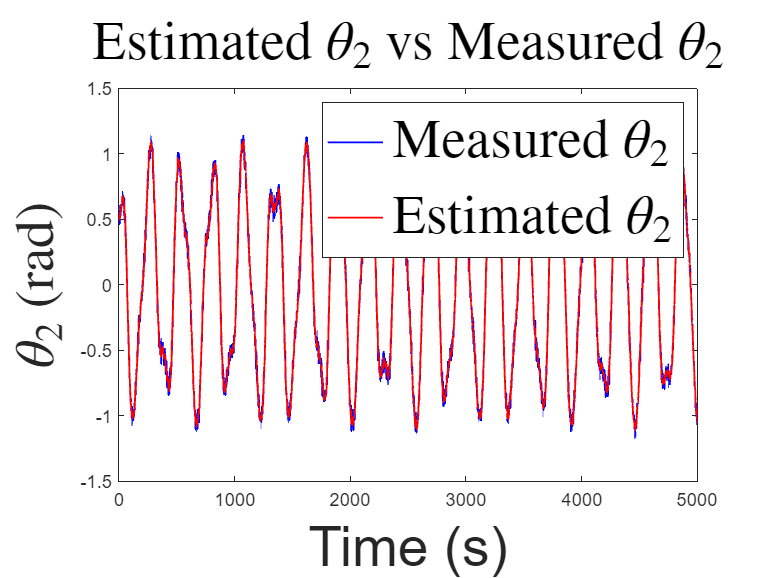

figure;
plot(time, theta2_measured, 'DisplayName', 'Measured $\theta_2$', 'Linewidth', 1.0, 'Color', 'b', 'LineStyle','-');
hold on
plot(time, x_hat_history(3, :), 'DisplayName', 'Estimated $\theta_2$', 'Linewidth', 1.0, 'Color', 'r', 'LineStyle','-');
hold off
xlabel('Time (s)', 'FontSize', 30);
ylabel('$\theta_2$ (rad)', 'Interpreter', 'Latex', 'FontSize', 30);
legend('Interpreter', 'Latex', 'FontSize', 30);
title('Estimated $\theta_2$ vs Measured $\theta_2$', 'Interpreter', 'Latex', 'FontSize', 30);

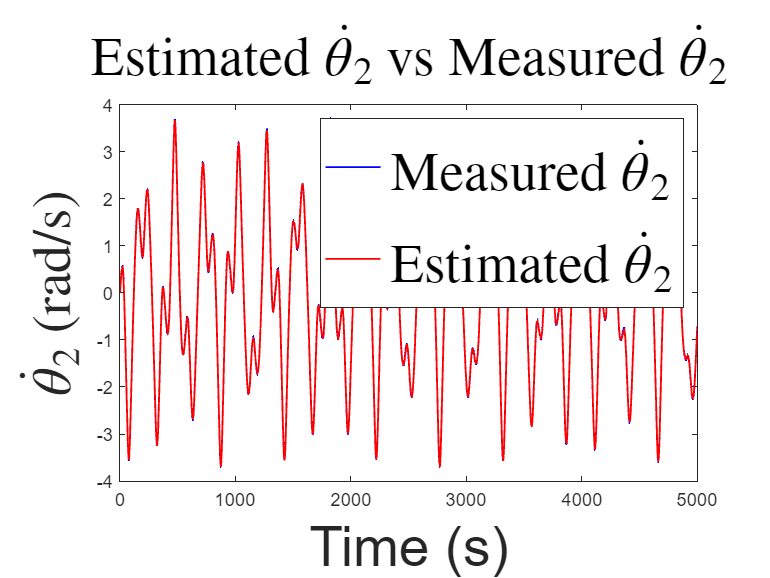

figure;
plot(time, theta2_dot_measured, 'DisplayName', 'Measured $\dot{\theta}_2$', 'Linewidth', 1.0, 'Color', 'b', 'LineStyle','-');
hold on
plot(time, x_hat_history(4, :), 'DisplayName', 'Estimated $\dot{\theta}_2$', 'Linewidth', 1.0, 'Color', 'r', 'LineStyle','-');
hold off
xlabel('Time (s)', 'FontSize', 30);
ylabel('$\dot{\theta}_2$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 30);
legend('Interpreter', 'Latex', 'FontSize', 30);
title('Estimated $\dot{\theta}_2$ vs Measured $\dot{\theta}_2$', 'Interpreter', 'Latex', 'FontSize', 30);

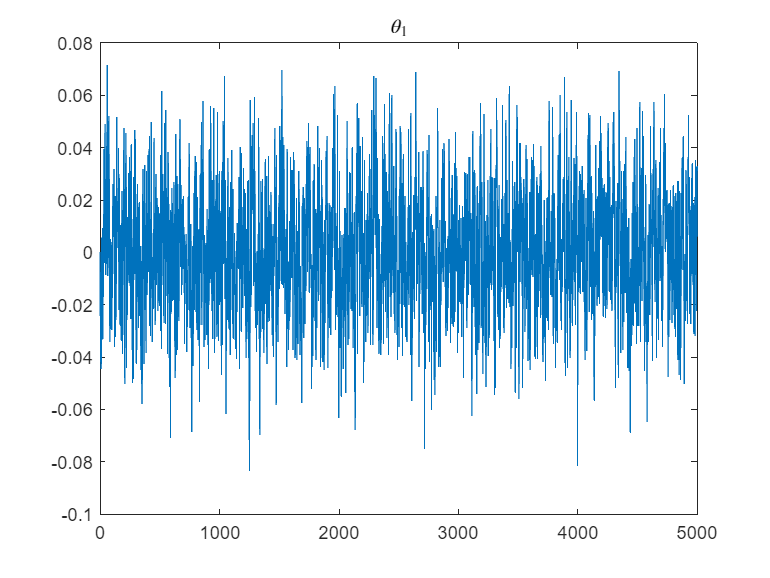

error1 = theta1_true' - x_hat_history(1, :);
plot(time, error1)
title('$\theta_1$', 'Interpreter', 'latex');

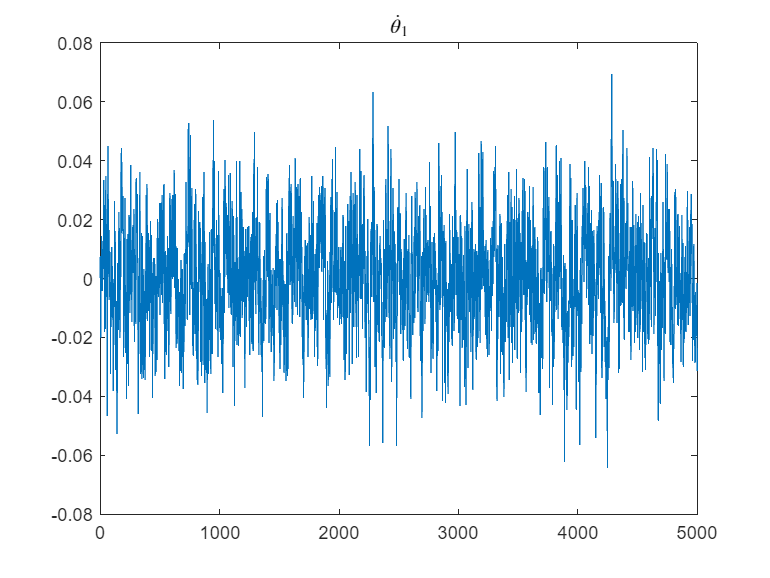

error2 = theta1_dot_true' - x_hat_history(2, :);
plot(time, error2)
title('$\dot{\theta}_1$', 'Interpreter', 'latex');

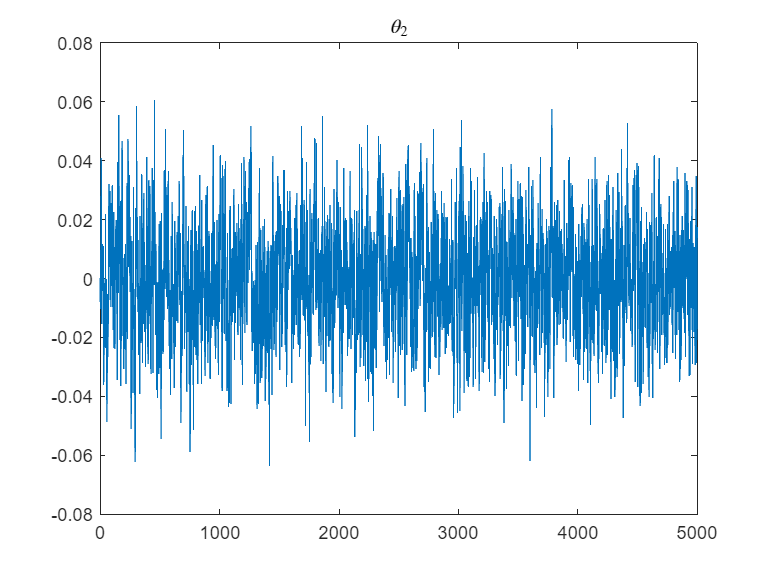

error3 = theta2_true' - x_hat_history(3, :);
plot(time, error3);
title('$\theta_2$', 'Interpreter', 'latex');

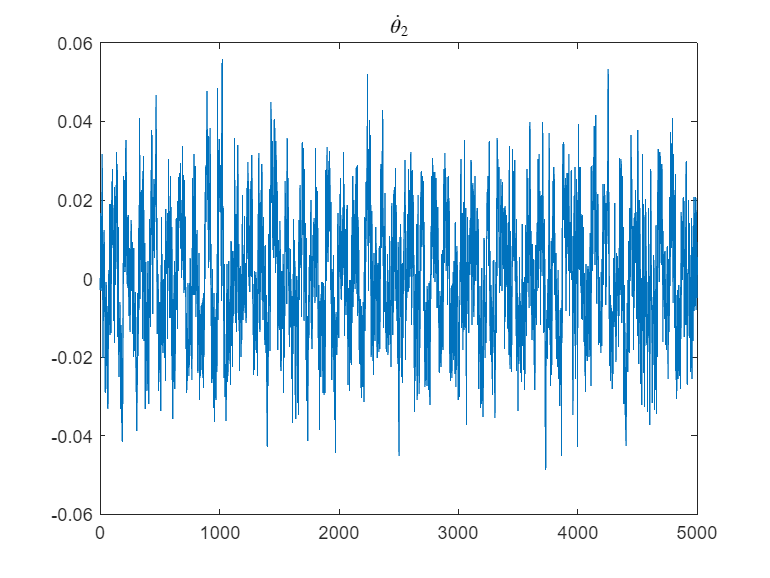

error4 = theta2_dot_true' - x_hat_history(4, :);
plot(time, error4);
title('$\dot{\theta}_2$', 'Interpreter', 'latex');

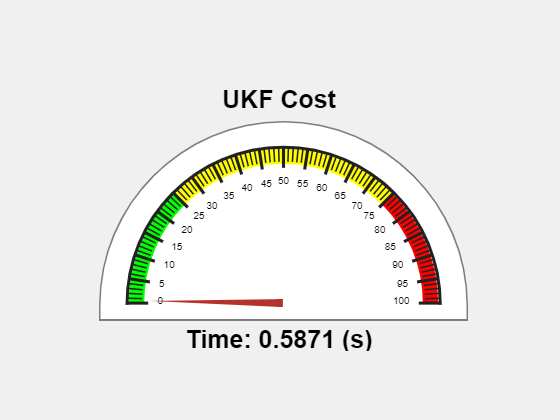

fig = uifigure('Name', 'UKF Cost');
gauge = uigauge(fig, 'semicircular');
gauge.Position = [100, 100, 400, 200];
gauge.Limits = [0 100];
gauge.Value = elapsed_time;
gauge.MajorTicks = 0:5:100;
gauge.FontSize = 10;

titleLabel = uilabel(fig, 'Text', 'UKF Cost');
titleLabel.Position = [180, 310, 200, 30];
titleLabel.HorizontalAlignment = 'center';
titleLabel.FontSize = 25;
titleLabel.FontWeight = 'bold';

valueLabel = uilabel(fig, 'Text', sprintf('Time: %.4f (s)', gauge.Value));
valueLabel.Position = [180, 70, 200, 30];
valueLabel.HorizontalAlignment = 'center';
valueLabel.FontSize = 25;
valueLabel.FontWeight = 'bold';

gauge.ScaleColors = [0 1 0; 1 1 0; 1 0 0];
gauge.ScaleColorLimits = [0 25; 25 75; 75 100];